**Ejemplo de aplicación de la FFT a una señal periodica.**

En este ejemplo se toma como base la misma señal de ejemplo del archivo formulado en excel. 

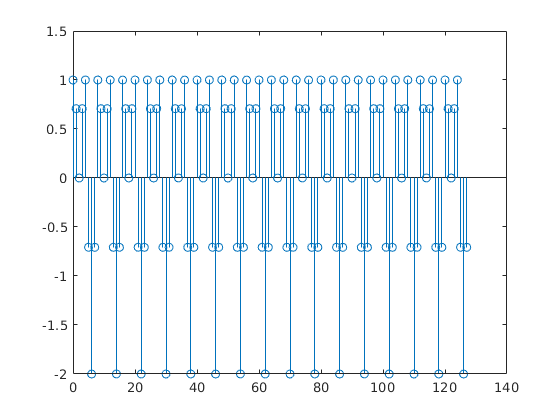

N=128; %número de muestras
n=0:N-1;
% Generación de los armónicos
Ar1=1*cos(2*pi*1/4*n);
Ar2=1*sin(2*pi*1/8*n);
Ar3=0*cos(2*pi*1/16*n);
Ar4=0*sin(2*pi*1/32*n);
Ar5=0*cos(2*pi*1/64*n);
xn=Ar1+Ar2+Ar3+Ar4+Ar5;
stem(n,xn)

Aplicación de la FFT

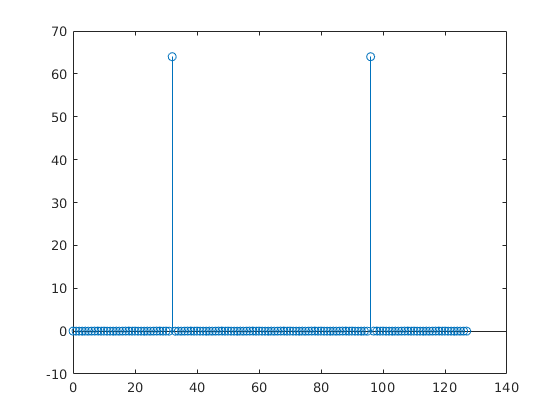

Xk=fft(xn);
figure
stem(n,real(Xk))

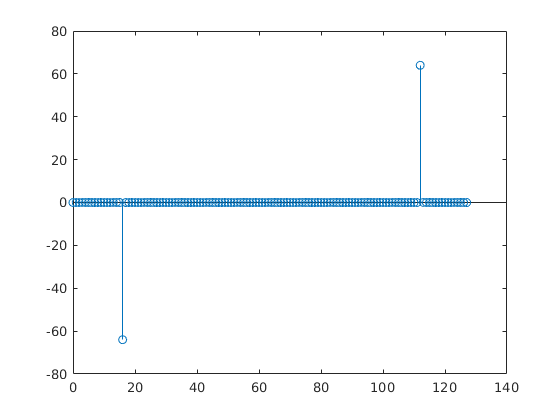

figure
stem(n,imag(Xk))

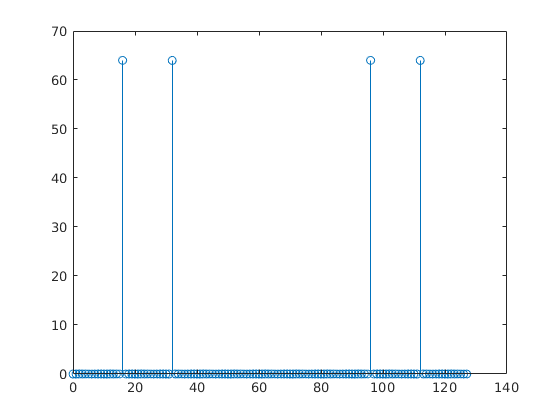

figure
stem(n,abs(Xk))

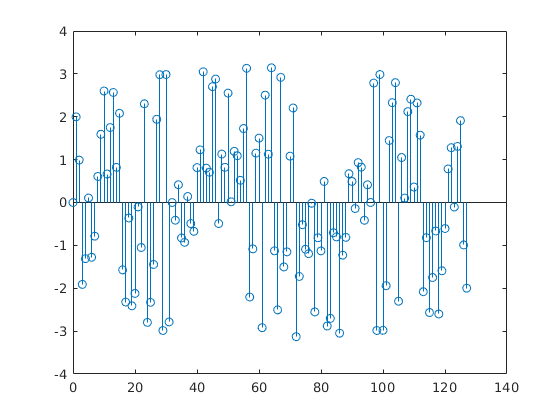

figure
stem(n,angle(Xk))

Observe que las gráficas tienen la misma forma, pero no los mismos valores.

Para obtener los mismos resultados que lo observado en el archivo de excel, hay que dividir los valores obtenidos con la fft entre el número total de muestras

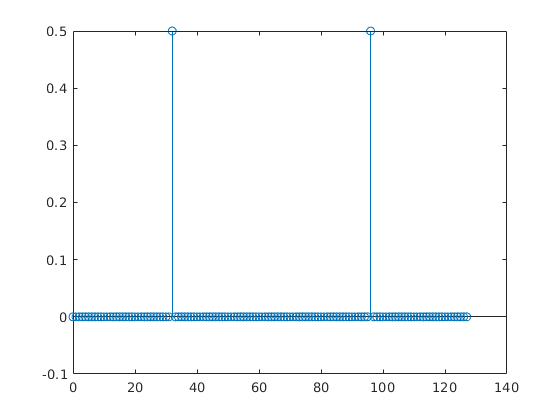

XkN=Xk/N;
figure
stem(n,real(XkN))

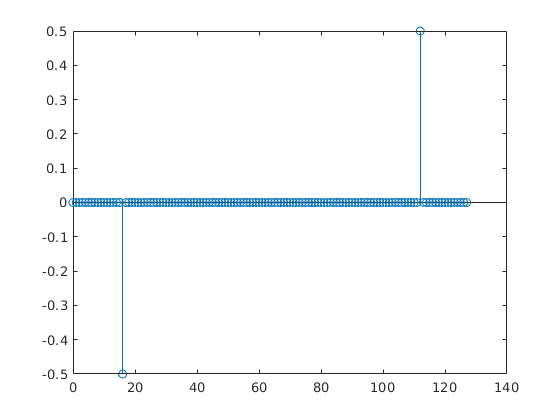

figure
stem(n,imag(XkN))

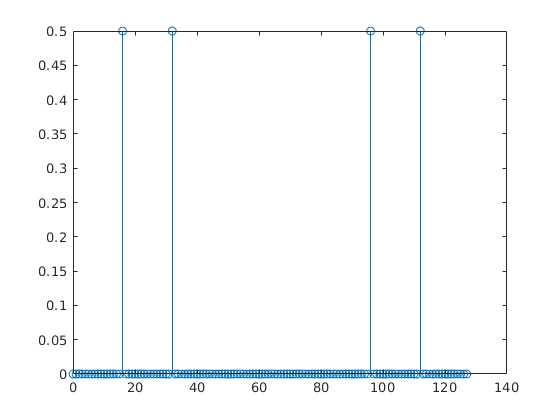

figure
stem(n,abs(XkN))

figure
stem(n,angle(XkN))